# Modern Control Theory Assignments

## 2024-2025-1

### Date: 2025.1.14           

# Control of Inverted Pendulum

### An inverted pendulum mounted on a motor-driven cart is shown in Figure 1(a). The inverted pendulum is unstable in that it may fall over any time in any direction unless a suitable control force is applied. Here we consider only a two-dimensional problem in which the pendulum moves only in the plane of the page. The control force u is applied to the cart. Assume that the center of gravity of the pendulum rod is at its geometric center. 

### 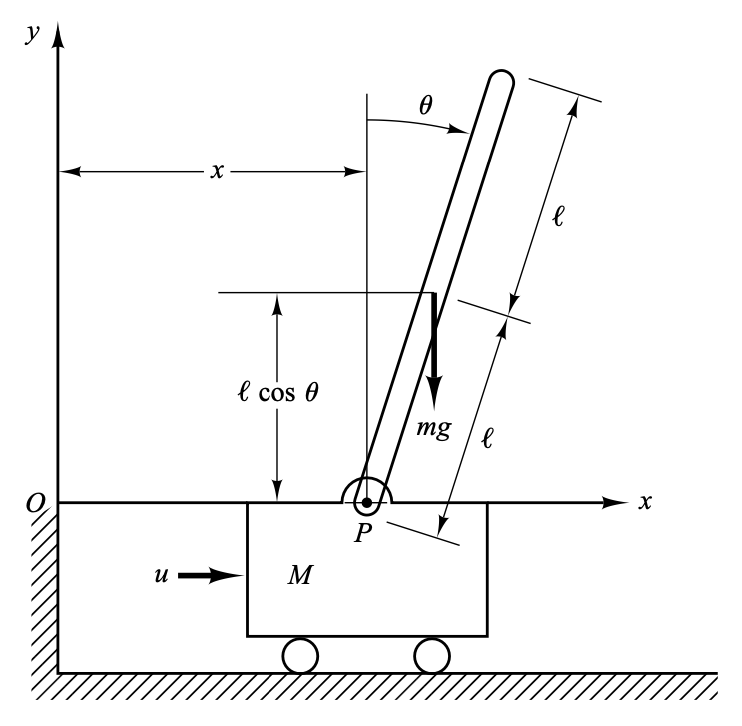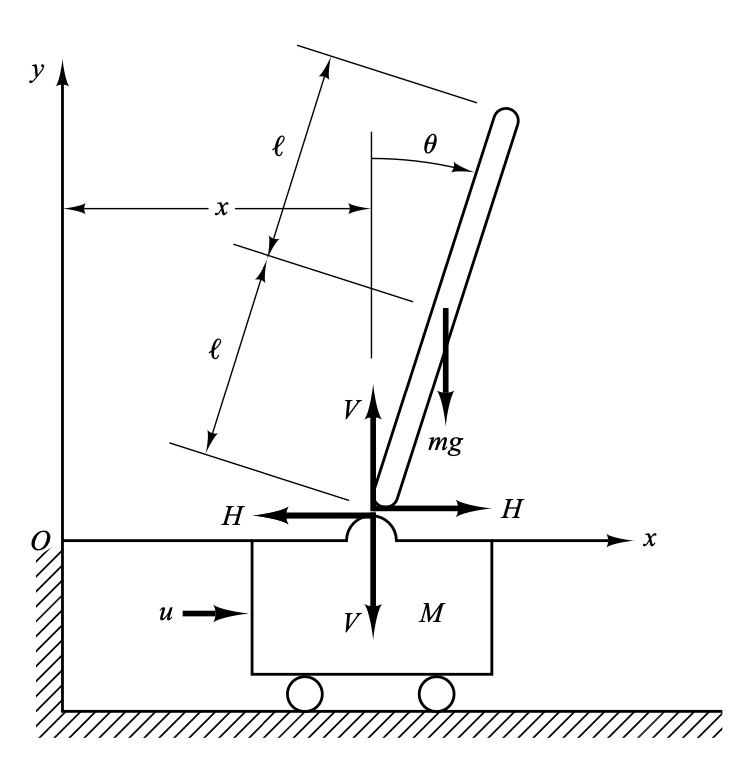

(a)                                                                      (b)

Figure 1: Schematical depiction of a inverted pendulum.

### Define the angle of the rod from the vertical line as $\theta$. Define also the coordinates of the point $P$ as $(x, y)$ and the center of gravity of the pendulum rod as $(x_G , y_G)$. Then

### $x_G =x+l \sin \theta \\
y_G =l \cos \theta$                                                                    (1)

### To derive the equations of motion for the system, consider the free-body diagram shown in

### Figure 1(b). The rotational motion of the pendulum rod about its center of gravity can be

### described by

### $I \ddot{\theta}=V l \sin \theta-H l \cos \theta$                                                    (2)

### where $I$ is the moment of inertia of the rod about its center of gravity.

### The horizontal motion of center of gravity of pendulum rod is given by

### $$$m \frac{d^2}{d t^2}(x+l \sin \theta)=H$$$                                                        (3)

### The vertical motion of center of gravity of pendulum rod is

### $$$m \frac{d^2}{d t^2}(l \cos \theta)=V-m g$$$                                                    (4)

### The horizontal motion of cart is described by

### $$$M \frac{d^2 x}{d t^2}=u-H$$$                                                                    (5)

### By taking derivertives, equations (3) and (4) become

### $m\left(\ddot{\theta} l \cos (\theta)+\ddot{x}-\dot{\theta}^2 l \sin (\theta)\right)=H$                                    (6)

### $-l m\left(\ddot{\theta} \sin (\theta)+\dot{\theta}^2 \cos (\theta)\right)=V-g m
$                                (7)

### From Equations (5) and (6), we obtain

### $(m+M) \ddot{x}+\ddot{\theta}m l \cos{\theta}-\dot{\theta}^2m l \sin {\theta}=u$                           (8)

### From Equations (2),(6) and (7), we have

### $\ddot{\theta}\left(I+l^2 m\right)+\ddot{x} l m \cos {\theta}-g l m \sin{\theta}=0$                           (9)

### Solve $\ddot{x}$ and $\ddot{\theta}$ from Equations (8) and (9), we get

### $\ddot{x}=\frac{\dot{\theta}^2\left(I l m \sin {\theta}+l^3 m^2 \sin {\theta}\right)-g l^2 m^2 \sin \theta \cos \theta-\left(I+l^2 m\right)u}{I(M+m)+M l^2 m+l^2 m^2 \sin ^2{\theta}}$      (10)

### $\ddot{\theta}=\frac{-\dot{\theta}^2 l^2 m^2 \sin {\theta} \cos {\theta}+ gl m(M+m) \sin {\theta}-ul m \cos {\theta}}{I(M+m)+M l^2 m+l^2 m^2 \sin ^2{\theta}}$                (11)

### Q.1 Try to get a nonliear state-space representation of the inverted pendulum system from equations (10) and (11), which outputs are chosen as $\theta$ and $x$.

### Solution:

### Q.2 Linearization: Since we must keep the inverted pendulum vertical, we can assume that  $\theta$ and $\dot \theta$ are small quantities such that $\dot\theta^2 \approx 0,\sin\theta\approx\theta, \cos\theta \approx 1,\sin^2\theta\approx 0$. Then, Equations (10) and (11) can be linearized, please write the linearized equations.

### Solution:

### Q.3 Try to get a the linear state-space representation of the linearized system in Q.2, and use the obtained state-space model to finish the following questions.

### Solution:

### We also assume that the numerical values for $M,m,l$and $I$ are given as, 

### 
$$M=2\text{kg},m=0.1\text{kg},l=0.5\text{m},I=0$$
                                            

### Substitude the values to the linear states-space model and finish the following questions.

### Q.4 Assess the stability properties of the given systems by employing the eigenvalue test.

### Solution:

A=[0 1 0 0;0 0 -0.49 0;0 0 0 1;0 0 20.58 0];
disp(eig(A))

### Q.5  Evaluate the controllability of the state-space model using appropriate criteria and methods.

### Solution:

B=[0;-0.5; 0; -1];
M=ctrb(A,B);

         0
         0
    4.5365
   -4.5365



[a,b]=size(M);
if rank(M)<min(a,b)
    disp("Matrix M is not full rank, the system is not full state controllable.");
else
    disp("Matrix M is full rank, the system is full state controllable.")
end

### Q.6  Evaluate the observability of the state-space model using appropriate criteria and methods.

### Solution:

C=[1 0 0 0;0 0 1 0];
N=obsv(A,C);
[a,b]=size(N);
if rank(N)<min(a,b)
    disp("Matrix N is not full rank, the system is not full state observable.");

Matrix M is full rank, the system is full state controllable.


else
    disp("Matrix N is full rank, the system is full state observable.");
end
N1=obsv(A,C(1,:));
[a,b]=size(N1);
if rank(N1)<min(a,b)
    disp("Matrix N1 is not full rank, the system is not full state observable.");
else
    disp("Matrix N1 is full rank, the system is full state observable.");
end

Matrix N is full rank, the system is full state observable.


### Q.7  Attempt to design a full-state feedback controller $$u(t)=K x(t),$$ let us choose the desired closed-loop poles at $s=\mu_i(i=1,2,3,4)$, where

### 
$$\mu_1=-1+j \sqrt{3}, \quad \mu_2=-1-j \sqrt{3}, \quad \mu_3=-5, \quad \mu_4=-5$$


### Solution:

n=length(A);
syms s
I=eye(n,n);
y=det(s*I-A );
a1=sym2poly(y) ;  
a=flip(a1); 
T1=zeros(n,n);

Matrix N1 is full rank, the system is full state observable.


T1(1,1)=1;
    for j=2:n
        for k=1:j-1
            T1(j , k)=a(n+2-j+k-1) ;
        end
        T1(j, j)=1;
    end
T1=flipud(T1);
p=[-1+sqrt(3)*1i -1-sqrt(3)*1i -5 -5];
syms s
f=(s-p(1))*(s-p(2))*(s-p(3))*(s-p(4));
a1=sym2poly(f);
f=det(s*I-A);
a=sym2poly(f);
a=flip(a);
a1=flip(a1);
a(end)=[];
a1(end)=[];
K1=-a+a1;
K=K1*inv(T1)*inv(M)
K=acker(A,B,p) %verify
eig(A-B*K)
A-B*K

### Q.8  Determine the state response and output response of the closed-loop system, given that the initial states $ $x(0)$$are non-zero and arbitrarily chosen. Plot the state responses. Both analytical calculations and MATLAB simulations are acceptable methods for this analysis. 

### Solution:

sys=ss(A-B*K,B,C,0);
x0=rand(1,4);
[y,tOut,x] = initial(sys,x0);
plot(tOut,x)
legend("x1","x2","x3","x4")

sys=ss(A,B,C,0);
x0=rand(1,4);
[y,tOut,x] = initial(sys,x0);

K =     9.2764    8.3488  -74.2182  -16.1744


plot(tOut,x)

K =     9.2764    8.3488  -74.2182  -16.1744


legend("x1","x2","x3","x4")

ans =   -5.0000 + 0.0000i
  -5.0000 + 0.0000i
  -1.0000 + 1.7321i
  -1.0000 - 1.7321i


### Q.9  Attempt to design a Luenberger observer for the given system by selecting suitable poles of the observer. Then, calculate the observer gain matrix $$G$$ to achieve this configuration, and provide the corresponding observer equation.

### Solution:

C=[1 0 1 0];

ans =          0    1.0000         0         0
    4.6382    4.1744  -37.5991   -8.0872
         0         0         0    1.0000
    9.2764    8.3488  -53.6382  -16.1744


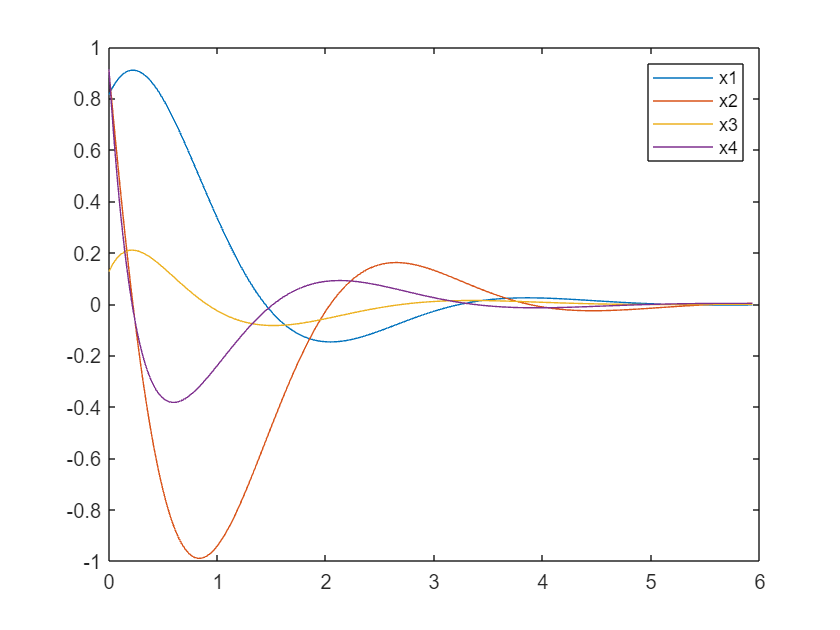

N=obsv(A,C);
n=length(A);
if rank(N)==n
    disp("The system is observable");
end
syms s
I=eye(n,n);
y=det(s*I-A);
a1=sym2poly(y) ; 
a=flip(a1); 

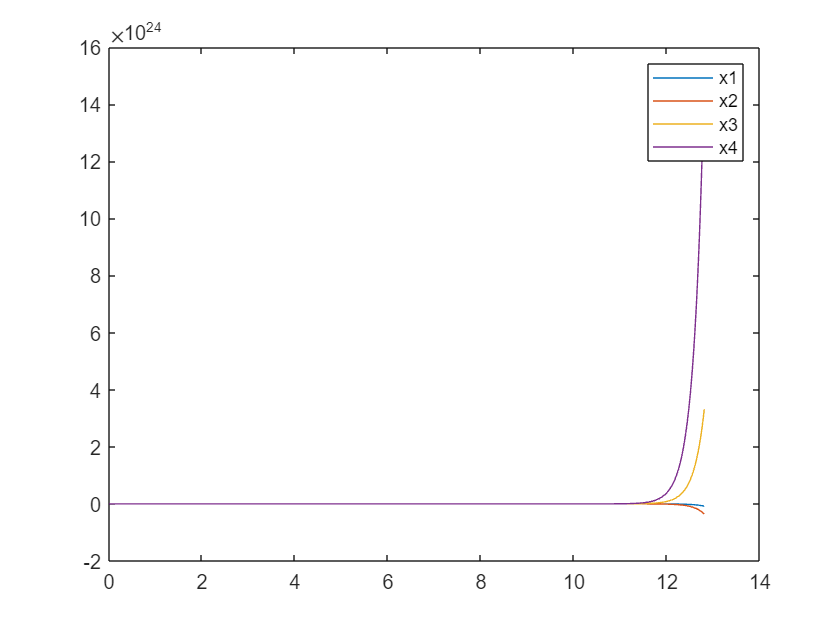

T1=zeros(n,n);
T1(1,1)=1;
    for j=2:n
        for k=1:j-1
            T1(j , k)=a(n+2-j+k-1) ;
        end

        T1(j, j)=1;
    end
T1=flipud(T1);
To=T1*N; 
syms s
p=[-10 -10 -10 -10];
f=(s-p(1))*(s-p(2))*(s-p(3))*(s-p(4));
a1=sym2poly(f);
f=det(s*I-A);

The system is observable


a=sym2poly(f);
a=flip(a);
a1=flip(a1);
a(end)=[];
a1(end)=[];
G=(-a+a1)';
G=inv(To)*G  
G=acker(A',C',p)'  %verify
eig(A-G*C)
A_obs=A-G*C

### Q.10  Construct the closed-loop system using a full-state observer and state feedback, and provide the state-space representation. Then, draw the structure diagram of this oberver-based closed-loop system.

### Solution:

K=-K;  %due to the state feed back in Matlab is A-B*K
B*K
G*C
A-G*C+B*K

### Q.11  Compare the state responses of the closed-loop system and the designed observer.  Select several different pairs of initial states for both the system and the observer. Then, plot both the original and estimated responses. Examine whether the observer is able to accurately follow the states of the original system. 

### Solution:

condition1=[0.1 0 0.08 0 0 0 0 0];
condition2=[0.15 0 0.1 0 0 0 0 0];
condition3=[0.5 0.1 0.1 0 0 0 0 0];
condition4=[0.5 0.1 0.1 0.1 0 0 0 0];
integrator_blocks = {
        'cartpole_with_obsever/Integrator1', ...
        'cartpole_with_obsever/Integrator2', ...
        'cartpole_with_obsever/Integrator3', ...
        'cartpole_with_obsever/Integrator4', ...
        'cartpole_with_obsever/Integrator5', ...

G = 1.0e+03 *

   -0.2001
   -0.5129
    0.2401
    1.1335


        'cartpole_with_obsever/Integrator6', ...

G = 1.0e+03 *

   -0.2001
   -0.5129
    0.2401
    1.1335


        'cartpole_with_obsever/Integrator7', ...

ans =  -10.0072 + 0.0000i
 -10.0000 + 0.0071i
 -10.0000 - 0.0071i
  -9.9929 + 0.0000i


        'cartpole_with_obsever/Integrator8'

A_obs = 1.0e+03 *

    0.2001    0.0010    0.2001         0
    0.5129         0    0.5124         0
   -0.2401         0   -0.2401    0.0010
   -1.1335         0   -1.1129         0


    };
 for i = 1:length(integrator_blocks)
        set_param(integrator_blocks{i}, 'InitialCondition', num2str(condition1(i)));
        disp(['Integrator ' num2str(i) ' InitialCondition: ' get_param(integrator_blocks{i}, 'InitialCondition')]);
 end

ans =          0         0         0         0
    4.6382    4.1744  -37.1091   -8.0872
         0         0         0         0
    9.2764    8.3488  -74.2182  -16.1744


simout=sim('cartpole_with_obsever.slx',[0,8]);    

ans = 1.0e+03 *

   -0.2001         0   -0.2001         0
   -0.5129         0   -0.5129         0
    0.2401         0    0.2401         0
    1.1335         0    1.1335         0


x1=simout.yout{1}.Values;

ans = 1.0e+03 *

    0.2001    0.0010    0.2001         0
    0.5175    0.0042    0.4753   -0.0081
   -0.2401         0   -0.2401    0.0010
   -1.1242    0.0083   -1.1871   -0.0162


x3=simout.yout{2}.Values;
x2=simout.yout{5}.Values;
x4=simout.yout{6}.Values;
x1_obs=simout.yout{3}.Values;
x3_obs=simout.yout{4}.Values;
x2_obs=simout.yout{7}.Values;
x4_obs=simout.yout{8}.Values;
time=x1.Time;
x1=x1.Data;
x3=x3.Data;
x2=x2.Data;
x4=x4.Data;
x1_obs=x1_obs.Data;
x3_obs=x3_obs.Data;
x2_obs=x2_obs.Data;
x4_obs=x4_obs.Data;
figure
plot(time,x1,"-",time,x1_obs,"-*");
legend('x1 origin', 'x1 observe');
grid on
xlabel("t"); ylabel("state response");
figure

Integrator 1 InitialCondition: 0.1
Integrator 2 InitialCondition: 0
Integrator 3 InitialCondition: 0.08
Integrator 4 InitialCondition: 0
Integrator 5 InitialCondition: 0
Integrator 6 InitialCondition: 0
Integrator 7 InitialCondition: 0
Integrator 8 InitialCondition: 0


plot(time,x3,"-",time,x3_obs,"-*");
legend('x3 origin', 'x3 observe');
grid on
xlabel("t"); ylabel("state response");

figure
plot(time,x2,"-",time,x2_obs,"-*");
legend('x2 origin', 'x2 observe'); grid on
xlabel("t"); ylabel("state response");

figure
plot(time,x4,"-",time,x4_obs,"-*");
legend('x4 origin', 'x4 observe'); grid on
xlabel("t"); ylabel("state response");

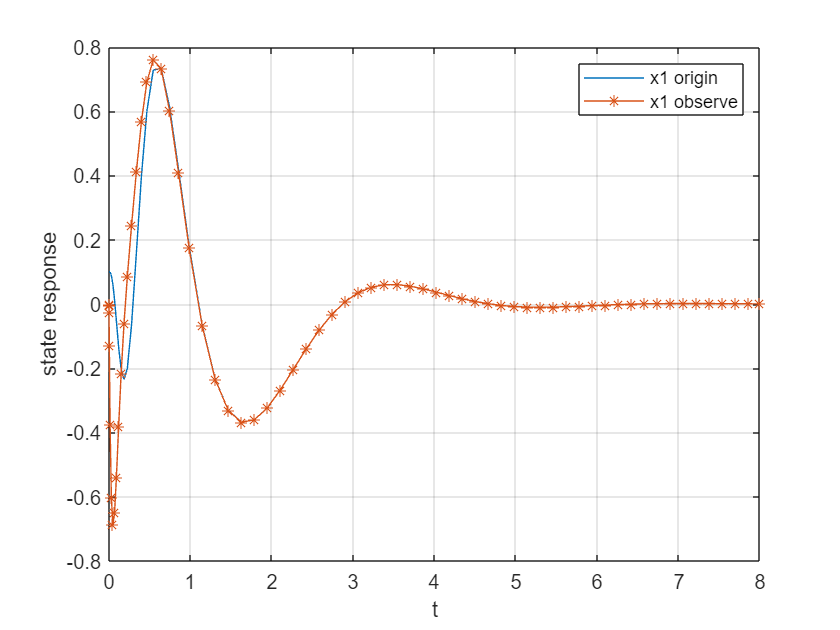

[x1,x3,x1_obs,x3_obs,time]=system(condition2);
figure
plot(time,x1,"-",time,x1_obs,"-*");
legend('x1 origin', 'x1 observe');
xlabel("t"); ylabel("state response")
grid on
figure
plot(time,x3,"-",time,x3_obs,"-*");
legend('x3 origin', 'x3 observe');
xlabel("t"); ylabel("state response")
grid on

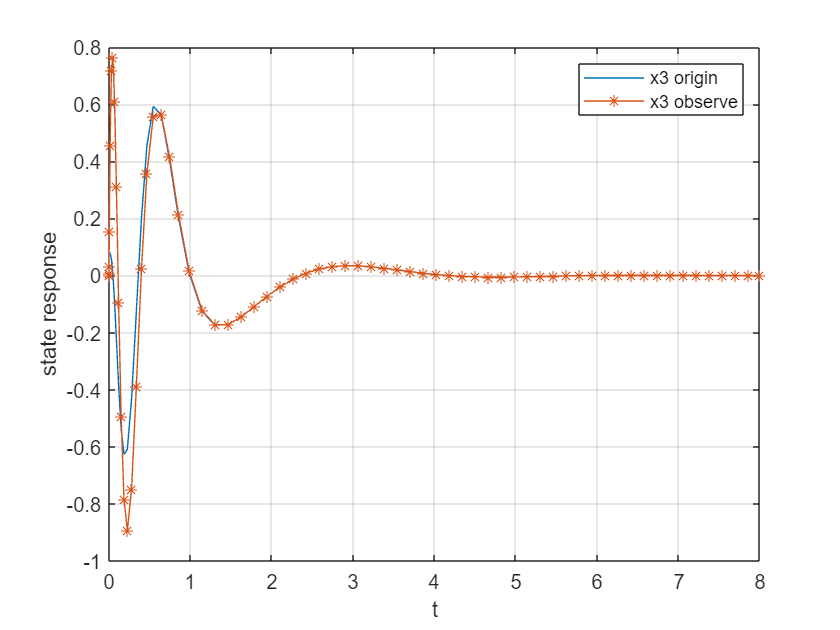

[x1,x3,x1_obs,x3_obs,time]=system(condition3);
plot(time,x1,"-",time,x1_obs,"-*");
legend('x1 origin', 'x1 observe');
xlabel("t"); ylabel("state response");
grid on

plot(time,x3,"-",time,x3_obs,"-*");
legend('x3 origin', 'x3 observe');
xlabel("t"); ylabel("state response");
grid on

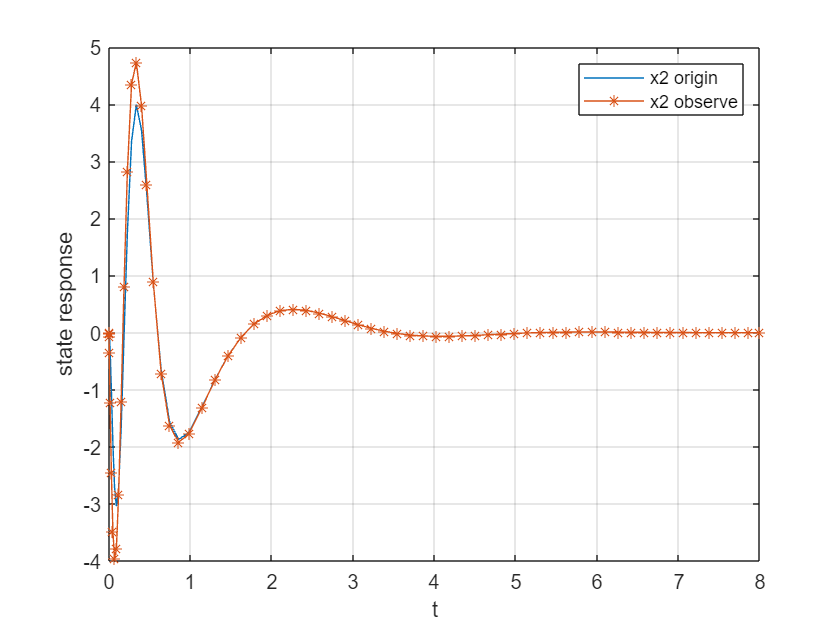

[x1,x3,x1_obs,x3_obs,time]=system(condition4);

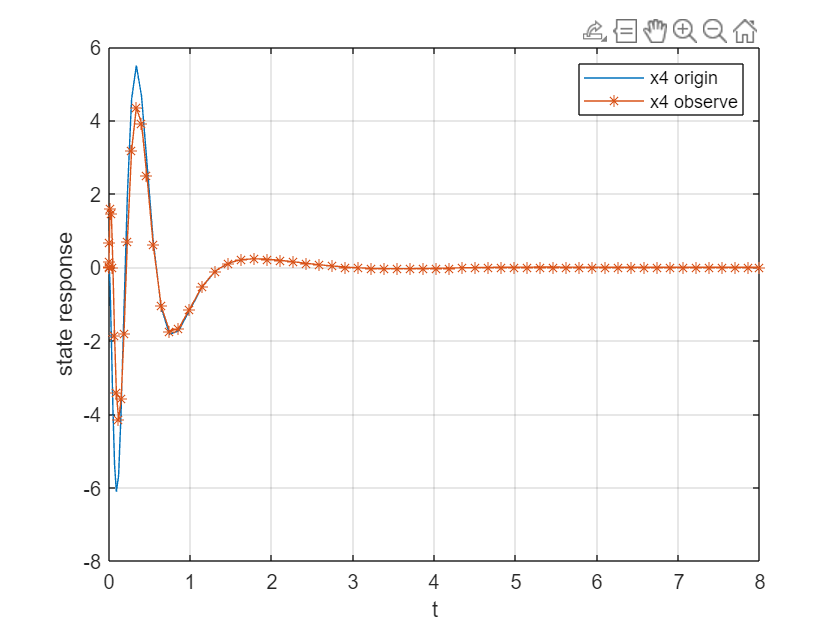

plot(time,x1,"-",time,x1_obs,"-*");
legend('x1 origin', 'x1 observe');
xlabel("t"); ylabel("state response");
grid on
plot(time,x3,"-",time,x3_obs,"-*");

legend('x3 origin', 'x3 observe');
xlabel("t"); ylabel("state response");

Integrator 1 InitialCondition: 0.15
Integrator 2 InitialCondition: 0
Integrator 3 InitialCondition: 0.1
Integrator 4 InitialCondition: 0
Integrator 5 InitialCondition: 0
Integrator 6 InitialCondition: 0
Integrator 7 InitialCondition: 0
Integrator 8 InitialCondition: 0


grid on

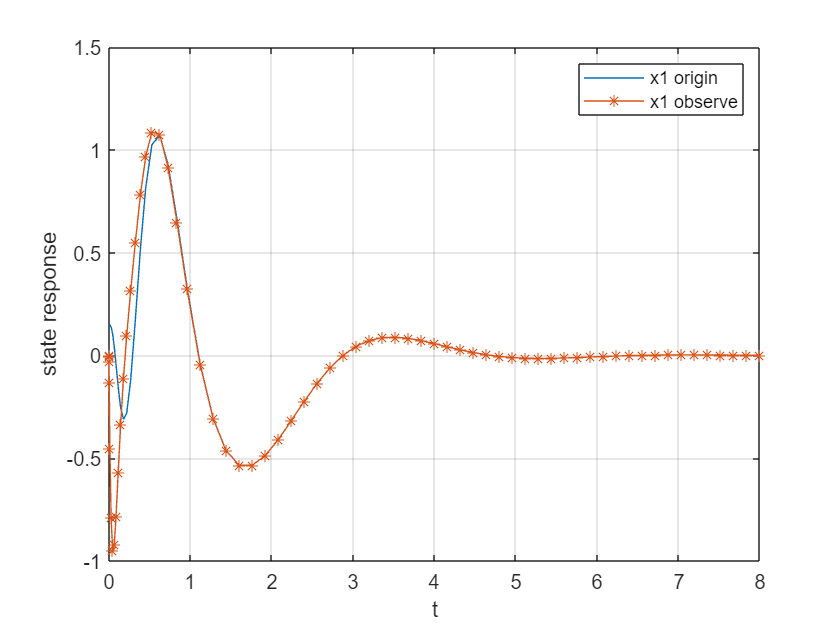

condition1=[0.2 0 0.1 0 0.2 0 0.1 0]; %the state of the observer is the same as origin system
condition2=[0.5 0 0.2 0 0.5 0 0.2 0];
[x1,x3,x1_obs,x3_obs,time]=system(condition1);
plot(time,x1,"-",time,x1_obs,"-*");

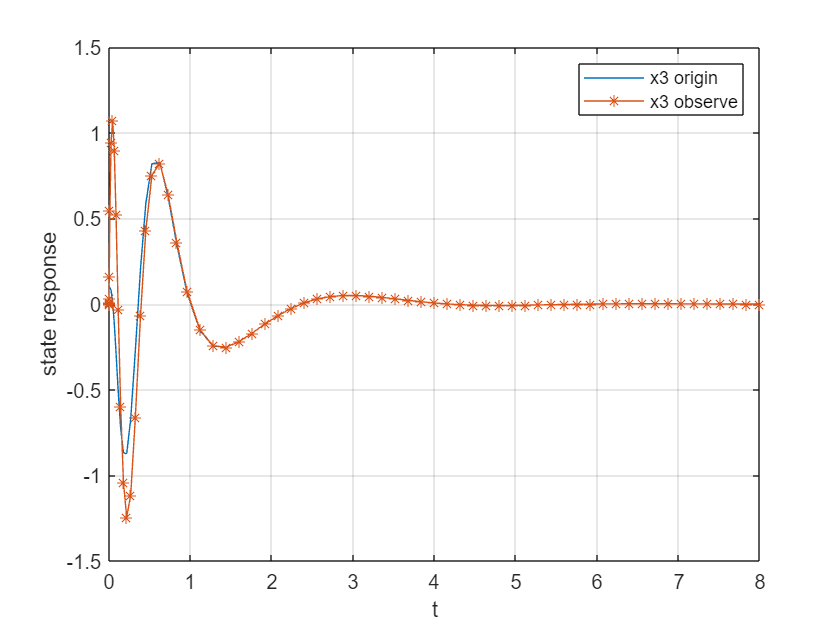

legend('x1 origin', 'x1 observe');
xlabel("t"); ylabel("state response");
grid on
plot(time,x3,"-",time,x3_obs,"-*");
legend('x3 origin', 'x3 observe');

xlabel("t"); ylabel("state response");
grid on

Integrator 1 InitialCondition: 0.5
Integrator 2 InitialCondition: 0.1
Integrator 3 InitialCondition: 0.1
Integrator 4 InitialCondition: 0
Integrator 5 InitialCondition: 0
Integrator 6 InitialCondition: 0
Integrator 7 InitialCondition: 0
Integrator 8 InitialCondition: 0


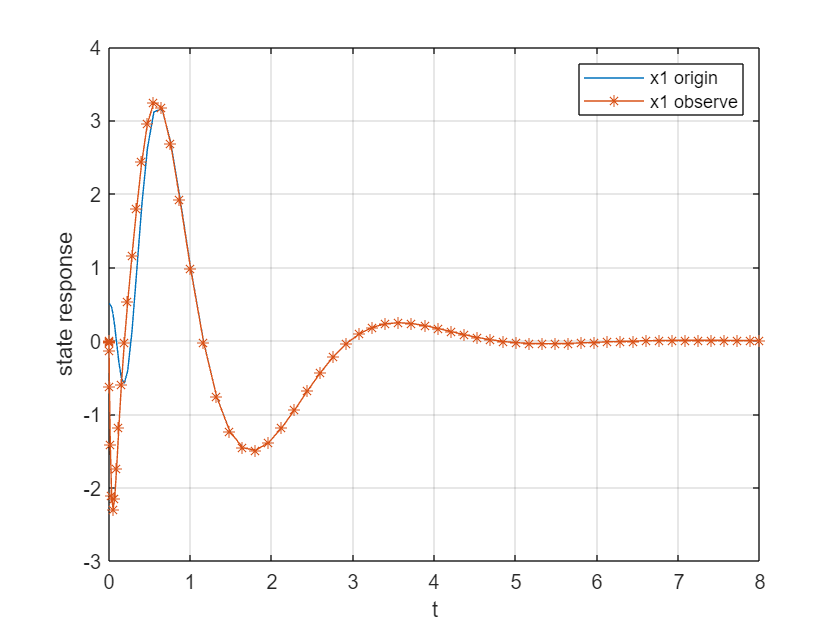

[x1,x3,x1_obs,x3_obs,time]=system(condition2);
plot(time,x1,"-",time,x1_obs,"-*");
legend('x1 origin', 'x1 observe');
xlabel("t"); ylabel("state response");

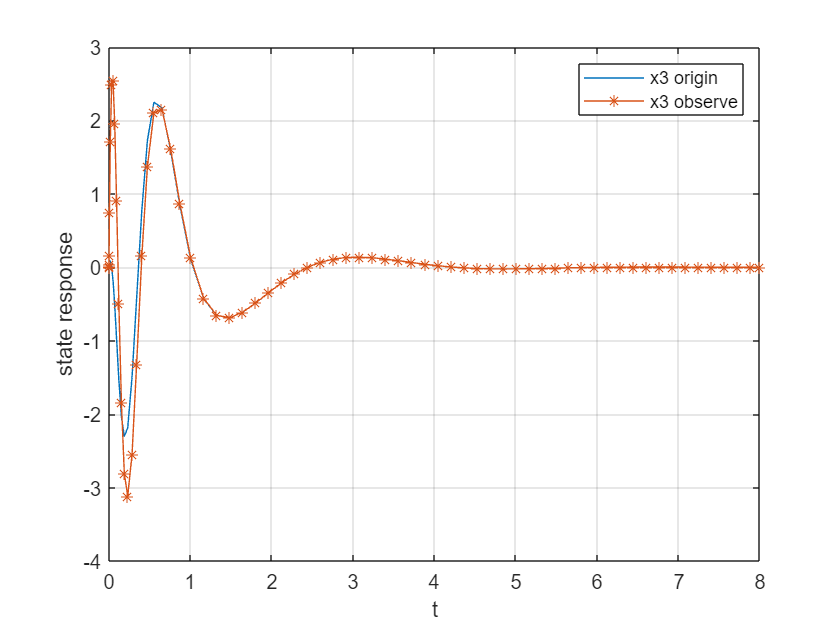

grid on
plot(time,x3,"-",time,x3_obs,"-*");
legend('x3 origin', 'x3 observe');
xlabel("t"); ylabel("state response");

grid on

### Further Discussion

C=[1 0 10 0]; %new observer

Integrator 1 InitialCondition: 0.5
Integrator 2 InitialCondition: 0.1
Integrator 3 InitialCondition: 0.1
Integrator 4 InitialCondition: 0.1
Integrator 5 InitialCondition: 0
Integrator 6 InitialCondition: 0
Integrator 7 InitialCondition: 0
Integrator 8 InitialCondition: 0


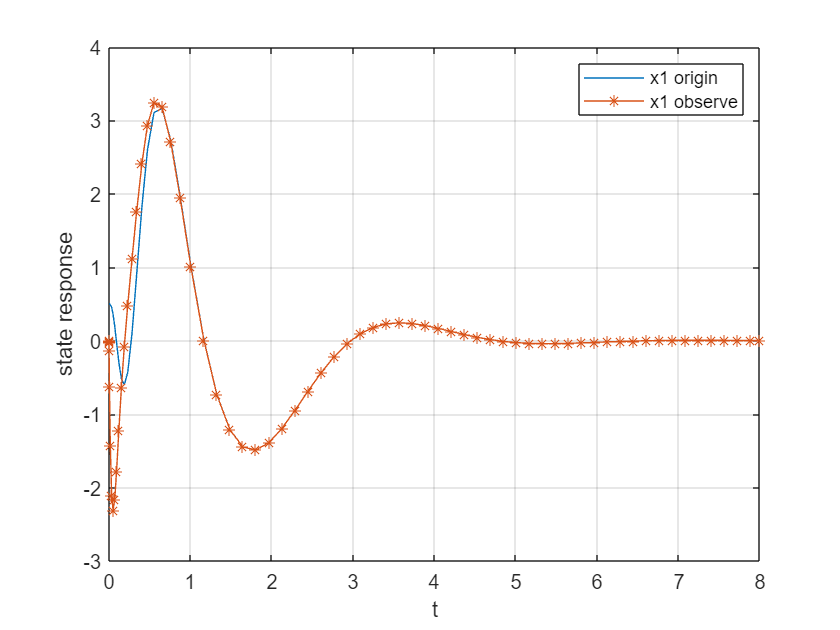

N=obsv(A,C);
rank(N)
p=[-10 -10 -10 -10];
G=acker(A',C',p)'

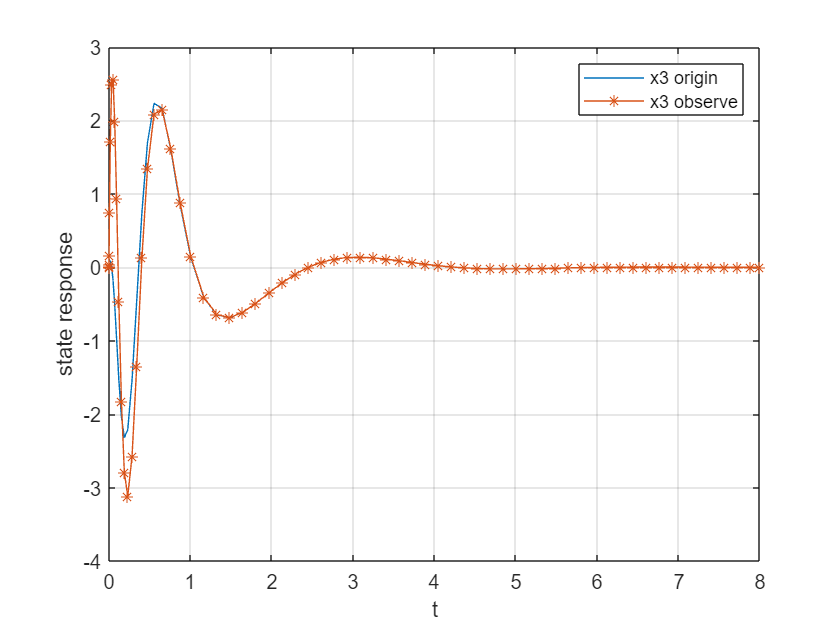

condition0=[3 0 0.3 0 0 0 0 0];
[x1,x3,x1_obs,x3_obs,time]=system_new(condition0);
plot(time,x1,"-",time,x1_obs,"-*");
legend('x1 origin', 'x1 observe');

xlabel("t"); ylabel("state response");
grid on
plot(time,x3,"-",time,x3_obs,"-*");
legend('x3 origin', 'x3 observe');

Integrator 1 InitialCondition: 0.2
Integrator 2 InitialCondition: 0
Integrator 3 InitialCondition: 0.1
Integrator 4 InitialCondition: 0
Integrator 5 InitialCondition: 0.2
Integrator 6 InitialCondition: 0
Integrator 7 InitialCondition: 0.1
Integrator 8 InitialCondition: 0


xlabel("t"); ylabel("state response");
grid on

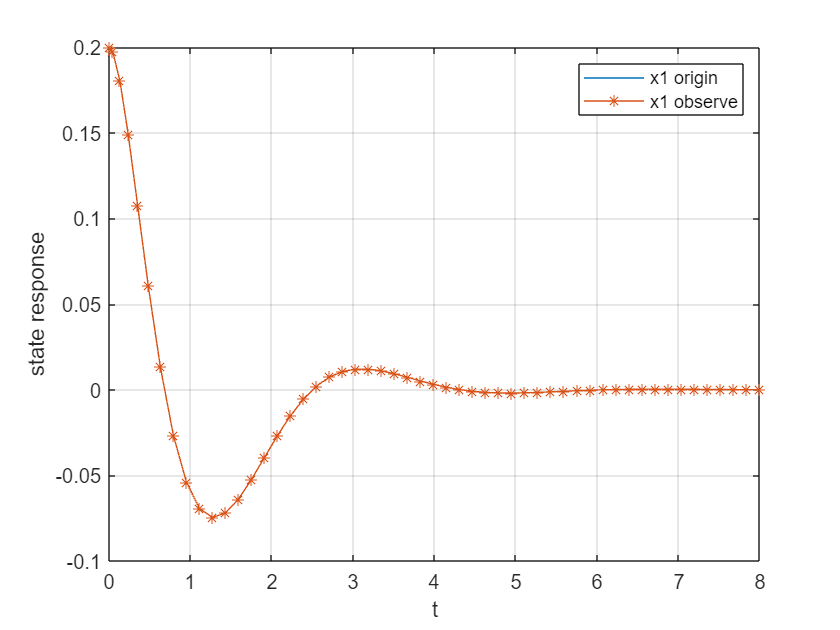

function [x1,x3,x1_obs,x3_obs,time]=system(x0)  %call simulink with initial condition
 integrator_blocks = {

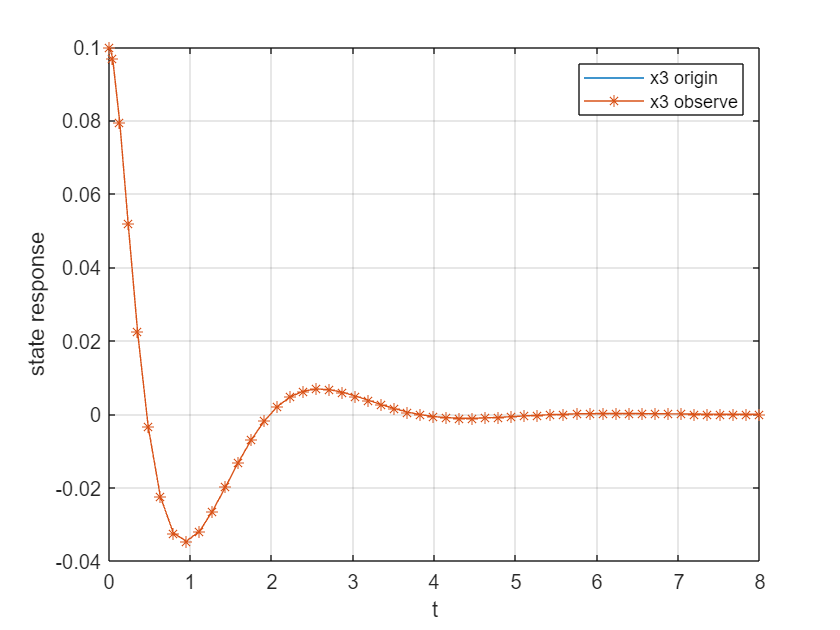

        'cartpole_with_obsever/Integrator1', ...
        'cartpole_with_obsever/Integrator2', ...
        'cartpole_with_obsever/Integrator3', ...
        'cartpole_with_obsever/Integrator4', ...

        'cartpole_with_obsever/Integrator5', ...
        'cartpole_with_obsever/Integrator6', ...

Integrator 1 InitialCondition: 0.5
Integrator 2 InitialCondition: 0
Integrator 3 InitialCondition: 0.2
Integrator 4 InitialCondition: 0
Integrator 5 InitialCondition: 0.5
Integrator 6 InitialCondition: 0
Integrator 7 InitialCondition: 0.2
Integrator 8 InitialCondition: 0


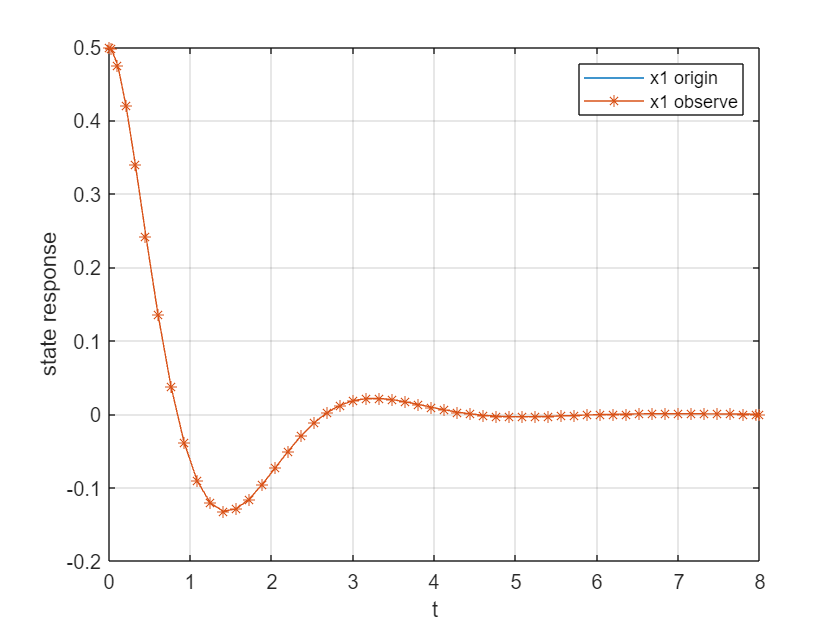

        'cartpole_with_obsever/Integrator7', ...
        'cartpole_with_obsever/Integrator8'
    };
 for i = 1:length(integrator_blocks)

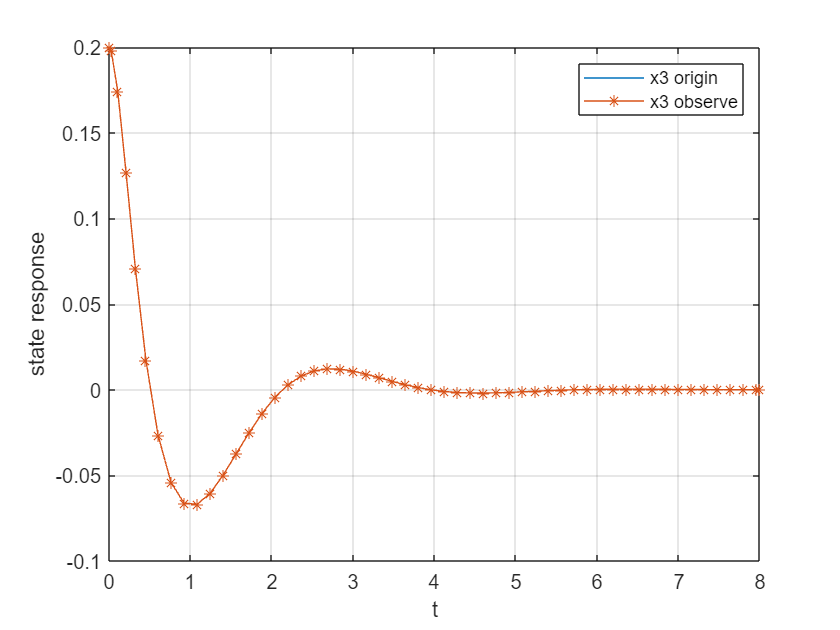

        set_param(integrator_blocks{i}, 'InitialCondition', num2str(x0(i)));
        disp(['Integrator ' num2str(i) ' InitialCondition: ' get_param(integrator_blocks{i}, 'InitialCondition')]);
 end
simout=sim('cartpole_with_obsever.slx',[0,8]);    

x1=simout.yout{1}.Values;
x3=simout.yout{2}.Values;
x1_obs=simout.yout{3}.Values;
x3_obs=simout.yout{4}.Values;
time=x1.Time;

ans = 4

x1=x1.Data;
x3=x3.Data;

G =  -194.9228
 -488.5494
   23.4923
  110.9129


Integrator 1 InitialCondition: 3
Integrator 2 InitialCondition: 0
Integrator 3 InitialCondition: 0.3
Integrator 4 InitialCondition: 0
Integrator 5 InitialCondition: 0
Integrator 6 InitialCondition: 0
Integrator 7 InitialCondition: 0
Integrator 8 InitialCondition: 0


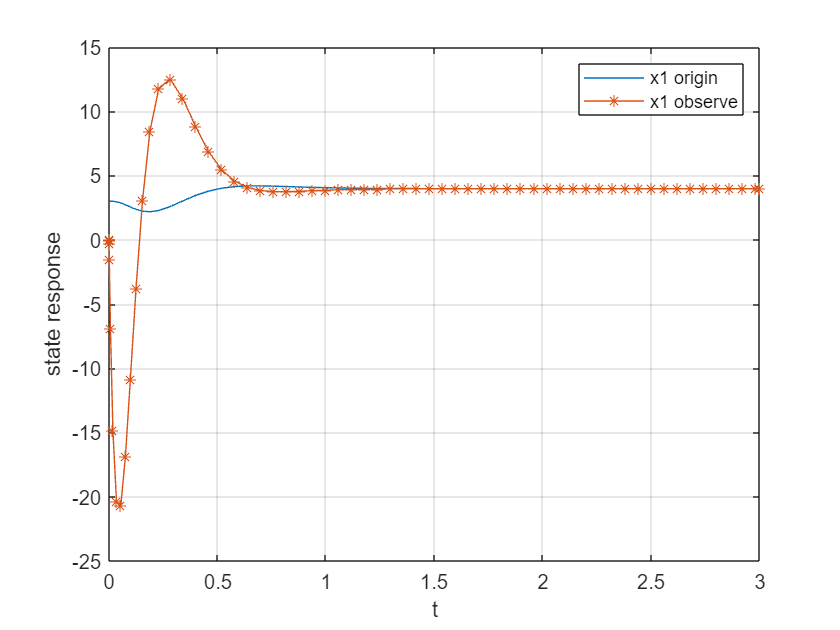

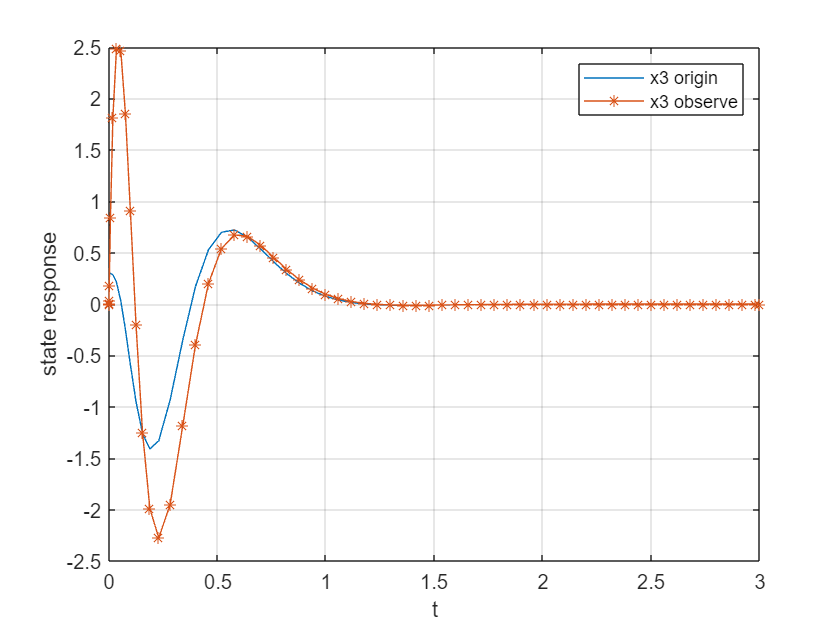

x1_obs=x1_obs.Data;
x3_obs=x3_obs.Data;
end